### Description: Code to calculate  FFT  and HHT  of signal with frequency modulated with components, noise and exponential decay.

### Author: Vishu Sharma

### Last Modified: 06.01.2022

clear all, clc

Fs = .5; % Sampling frequency
T = 1/Fs; % Sampling period
L = 2048; % length of signal
t = (0: L-1)*T;
r=2*pi;

## Signal and Noise


A = 1.2*sin(1/25*r*t);
B = 1.2*sin(1/33*r*t);

E = exp(-0.001.*t);
N = 0.1*rand(size(t));

x = A.*E + B.*N + B.*A ;


## Signal in time domain

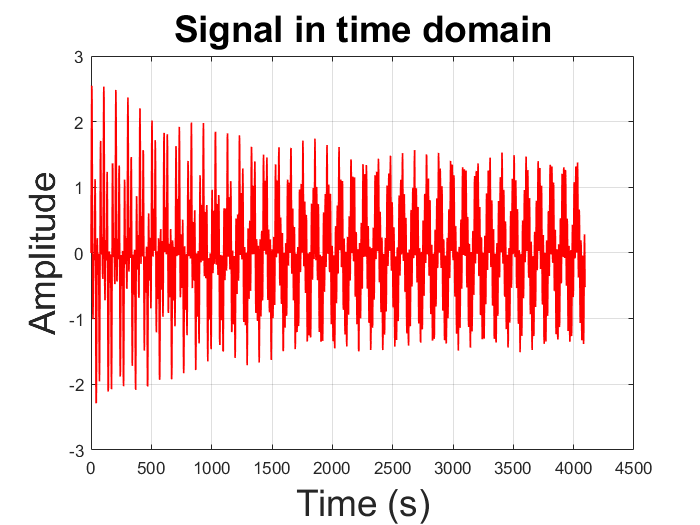

plot(t,x, 'r','LineWidth',1)
grid on
title('Signal in time domain', 'FontSize', 22)
xlabel('Time (s)','FontSize', 22)
ylabel('Amplitude', 'FontSize', 22)

## Fourier Spectral Analysis

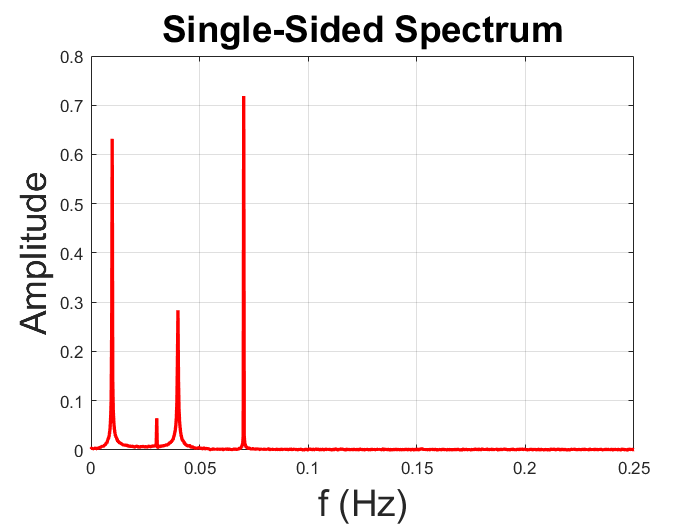

n = 2^nextpow2(L);         % num of points for FFT

Y = fft(x);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1,'r','LineWidth',2) 

title('Single-Sided Spectrum','FontSize', 22)
xlabel('f (Hz)','FontSize', 22)
ylabel('Amplitude', 'FontSize', 22)

grid on

## Spectogram

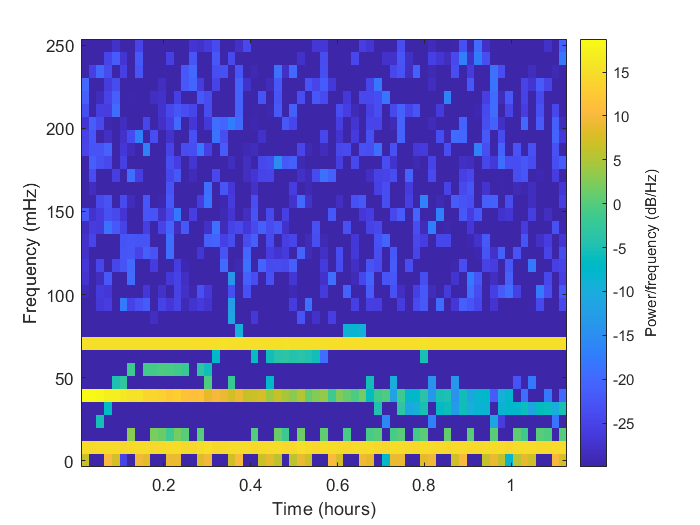

 s = spectrogram(x);
 spectrogram(x, window(@blackman,64), 32, 64, Fs,'yaxis', 'reassign','MinThreshold', -30)

## Waterfall Plot

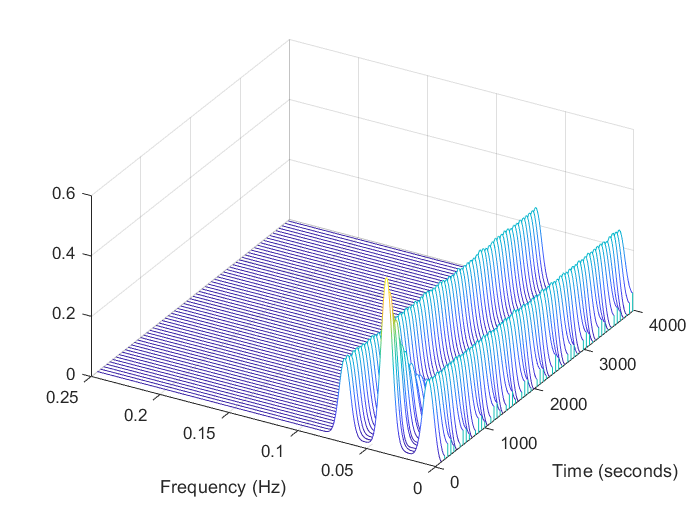

[p,f2,t1] = pspectrum(x,Fs,'spectrogram');

waterfall(f2,t1,p')
xlabel('Frequency (Hz)')
ylabel('Time (seconds)')
wtf = gca;
wtf.XDir = 'reverse';
view([30 45])

## HHT

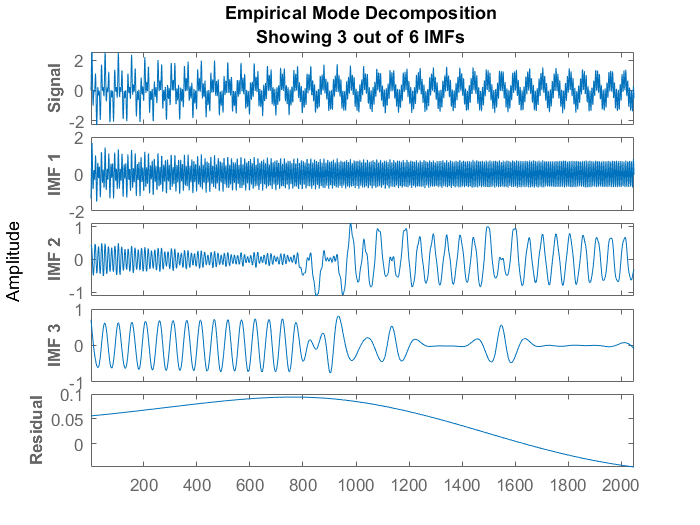

%hht(x)

emd(x,'MaxNumIMF',6)

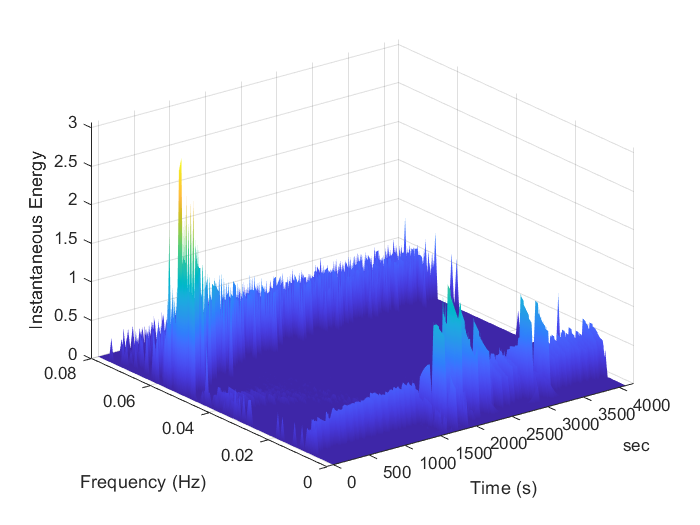

imf = emd(x);
[hs,F,t] = hht(imf,Fs,'FrequencyLimits',[0 .08]);

mesh(seconds(t),F,hs,'EdgeColor','none','FaceColor','interp')
xlabel('Time (s)')
ylabel('Frequency (Hz)')
zlabel('Instantaneous Energy')